# Prepare the SAMAN dataset

% clear the environment 
clear all 
close all 
clc 

% read the data from file 
data = read_dataset_file("final-saman-dataset.csv");
features = [];

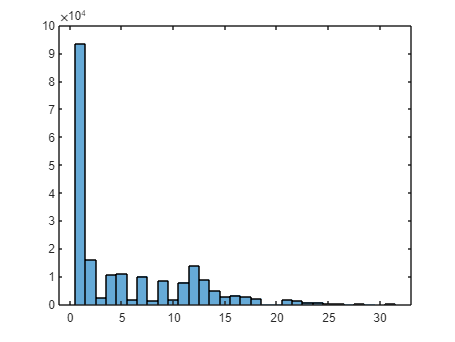

% Province 
province_data = data(:, 1);
histogram(province_data)

k =        93542       16066        2535       10581       10851        1781       10077        1413        8547        1719        7929       13818        8955        4735        2759        3279        2820        2176          58          40        1673        1174         781         745         313         343          46         163          29           4         136


p =    44.7381    7.6838    1.2124    5.0605    5.1897    0.8518    4.8195    0.6758    4.0878    0.8221    3.7922    6.6087    4.2829    2.2646    1.3195    1.5682    1.3487    1.0407    0.0277    0.0191    0.8001    0.5615    0.3735    0.3563    0.1497    0.1640    0.0220    0.0780    0.0139    0.0019    0.0650


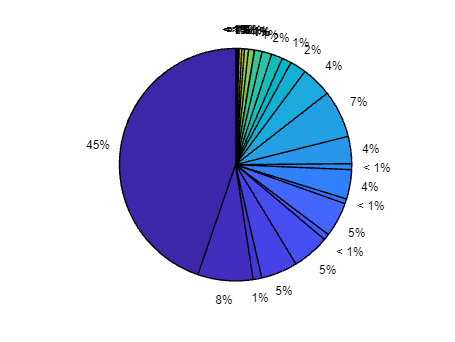

out =    44.7381    7.6838    1.2124    5.0605    5.1897    0.8518    4.8195    0.6758    4.0878    0.8221    3.7922    6.6087    4.2829    2.2646    1.3195    1.5682    1.3487    1.0407    0.0277    0.0191    0.8001    0.5615    0.3735    0.3563    0.1497    0.1640    0.0220    0.0780    0.0139    0.0019    0.0650


p =    44.7381    7.6838    1.2124    5.0605    5.1897    0.8518    4.8195    0.6758    4.0878    0.8221    3.7922    6.6087    4.2829    2.2646    1.3195    1.5682    1.3487    1.0407    0.0277    0.0191    0.8001    0.5615    0.3735    0.3563    0.1497    0.1640    0.0220    0.0780    0.0139    0.0019    0.0650


p = draw_pie(province_data)

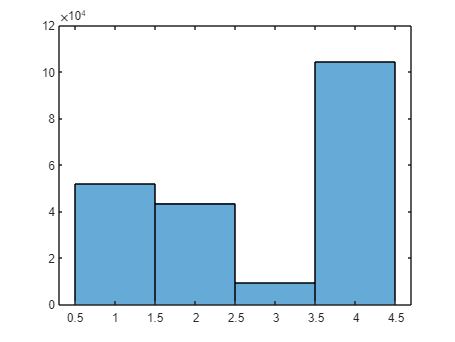

% set the group data 
density_data = data(:, 2);
density_group_1 = find(density_data < 50);
density_group_2 = find(density_data >= 50 & density_data < 100);
density_group_3 = find(density_data >= 100 & density_data < 200);
density_group_4 = find(density_data >= 200);

density_data(density_group_1) = 1;
density_data(density_group_2) = 2;
density_data(density_group_3) = 3;
density_data(density_group_4) = 4;

histogram(density_data)

k =        51946       43475        9274      104393


p =    24.8441   20.7927    4.4355   49.9278


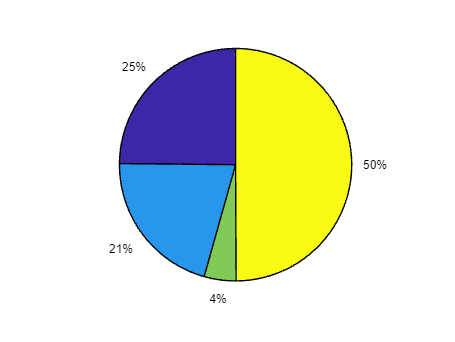

out =    24.8441   20.7927    4.4355   49.9278


p =    24.8441   20.7927    4.4355   49.9278


p = draw_pie(density_data)

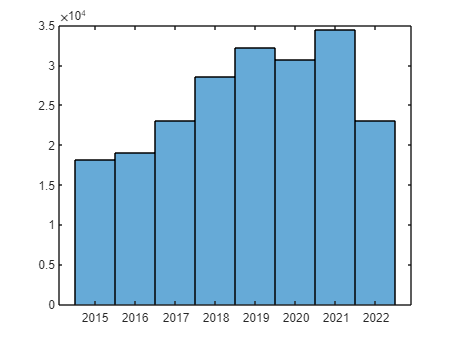

% issue date year 
issue_date = data(:, 3);
issue_date = issue_date - 1393 + 2014;

histogram(issue_date)

k =        18128       19060       23049       28532       32158       30662       34425       23074


p =     8.6700    9.1158   11.0236   13.6459   15.3801   14.6646   16.4644   11.0355


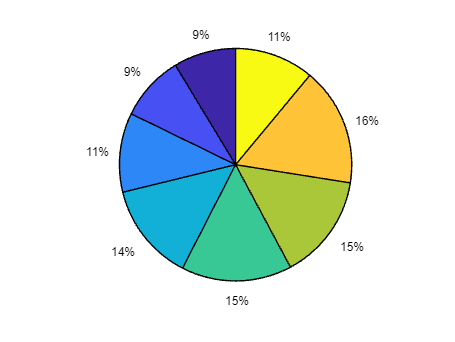

out =     8.6700    9.1158   11.0236   13.6459   15.3801   14.6646   16.4644   11.0355


p =     8.6700    9.1158   11.0236   13.6459   15.3801   14.6646   16.4644   11.0355


p = draw_pie(issue_date)

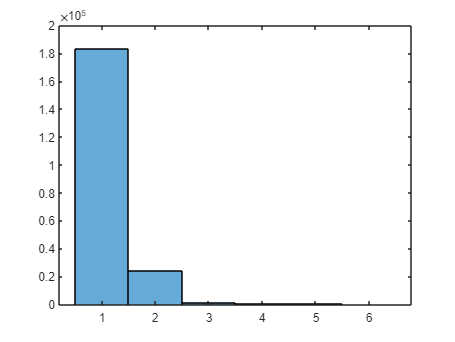

% car type 
car_type = data(:, 5);
histogram(car_type)

k =       183334       23953        1024         499         246          32


p =    87.6827   11.4559    0.4897    0.2387    0.1177    0.0153


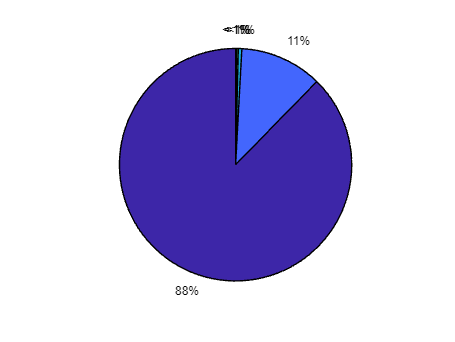

out =    87.6827   11.4559    0.4897    0.2387    0.1177    0.0153


p =    87.6827   11.4559    0.4897    0.2387    0.1177    0.0153



p = draw_pie(car_type)

% car usage 
car_usage = data(:, 6);

k = hist(car_usage, unique(car_usage))

k =       177727        1115         414        3124          21       12523         885        2578         198         353        1066         488         936         549          22         406          54          18         410         133           9         513         454          71         123          45        3414         125          88          13          69         181          83          41           6          23           9          45          61          81         245          33          77          28          26          25           8          14           7           5


p = k./length(car_usage)*100

p =    85.0011    0.5333    0.1980    1.4941    0.0100    5.9893    0.4233    1.2330    0.0947    0.1688    0.5098    0.2334    0.4477    0.2626    0.0105    0.1942    0.0258    0.0086    0.1961    0.0636    0.0043    0.2454    0.2171    0.0340    0.0588    0.0215    1.6328    0.0598    0.0421    0.0062    0.0330    0.0866    0.0397    0.0196    0.0029    0.0110    0.0043    0.0215    0.0292    0.0387    0.1172    0.0158    0.0368    0.0134    0.0124    0.0120    0.0038    0.0067    0.0033    0.0024



% merge the groups with less than 0.5% samples 
removeSmallUsageGroups = 0.5;
index = find( p < removeSmallUsageGroups);

for i = 1 : length(index)
    car_usage(find(car_usage == index(i))) = 72;
end 

unique_categories = unique(car_usage)

unique_categories =      1
     2
     4
     6
     8
    11
    27
    72


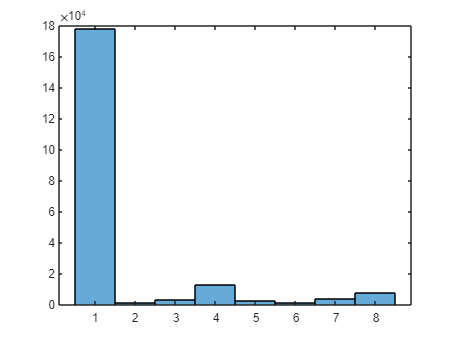


for i = 1 : length(unique_categories)
    car_usage(find(car_usage == unique_categories(i))) = 100+i;
end 

car_usage = car_usage - 100;

histogram(car_usage)

k =       177727        1115        3124       12523        2578        1066        3414        7541


p =    85.0011    0.5333    1.4941    5.9893    1.2330    0.5098    1.6328    3.6066


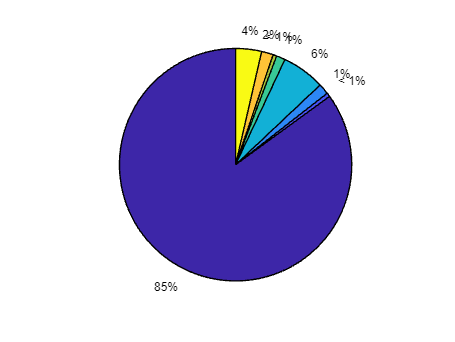

out =    85.0011    0.5333    1.4941    5.9893    1.2330    0.5098    1.6328    3.6066


p =    85.0011    0.5333    1.4941    5.9893    1.2330    0.5098    1.6328    3.6066


p = draw_pie(car_usage)

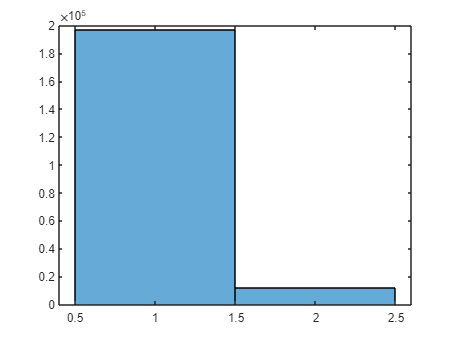

% duration of policy 
duration_policy = data(:, 8);
duration_policy(find(duration_policy <= 365)) = 1; 
duration_policy(find(duration_policy > 365)) = 2; 

histogram(duration_policy)

k =       197149       11939


p =    94.2900    5.7100


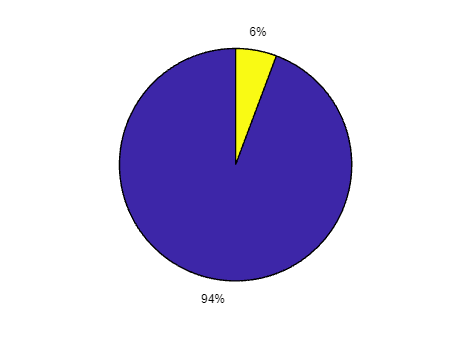

out =    94.2900    5.7100


p =    94.2900    5.7100



p = draw_pie(duration_policy)

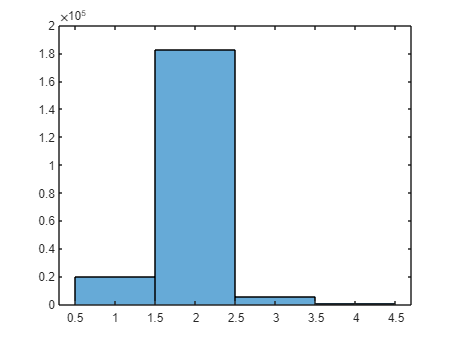

% number of passengers 
passengers = data(:, 10);
passengers(find(passengers >= 10)) = 104; 
passengers(find(passengers >= 6 & passengers < 10)) = 103; 
passengers(find(passengers >= 3 & passengers < 6)) = 102; 
passengers(find(passengers < 3)) = 101; 

passengers = passengers - 100;

histogram(passengers)

k =        20123      182350        5772         843


p =     9.6242   87.2121    2.7606    0.4032


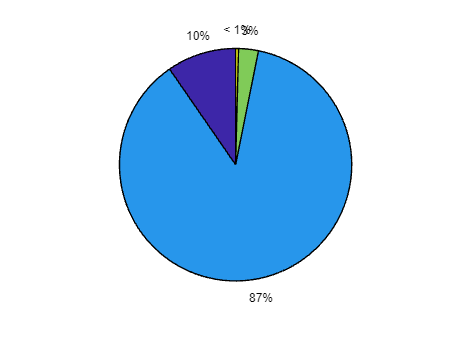

out =     9.6242   87.2121    2.7606    0.4032


p =     9.6242   87.2121    2.7606    0.4032


p = draw_pie(passengers)

% number of cylindar 
cylinders = data(:, 11);

k = hist(cylinders, unique(cylinders));
p = k./length(cylinders)*100

p =     0.0263    0.2348    0.0033    0.3458   94.0657    0.0249    5.1050    0.1918    0.0024


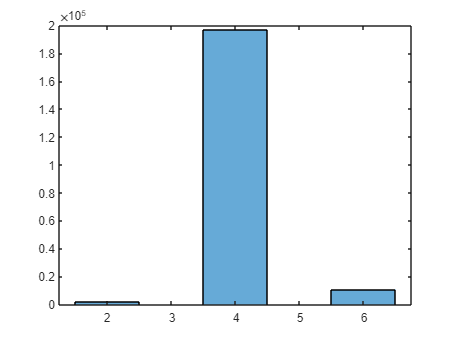


% merge the groups with less than 0.5% samples 
removeSmallGroups = 0.5;
index = find( p < removeSmallGroups) - 1;

cylinders(find(cylinders ~= 4 & cylinders ~= 6)) = 2;

histogram(cylinders)

k =         1734      196680       10674


p =     0.8293   94.0657    5.1050


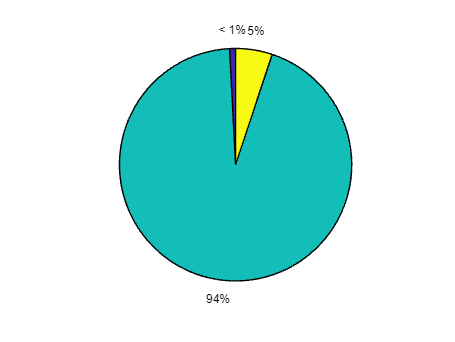

out =     0.8293   94.0657    5.1050


p =     0.8293   94.0657    5.1050


p = draw_pie(cylinders)

% Car Price 
car_price = data(:, 13);
eco_class = find(car_price <= 5000000000)

eco_class =      3
     4
     5
     6
     7
     8
     9
    10
    11
    12


mid_calss = find(car_price > 5000000000 & car_price <= 10000000000)

mid_calss =      1
    15
    37
    38
    42
    46
    57
    62
    77
    93


lux_class = find(car_price > 10000000000)

lux_class =      2
    13
    59
    70
    76
    83
    90
   131
   161
   177


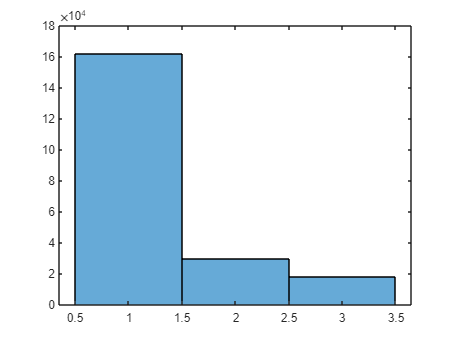


car_price(eco_class) = 1;
car_price(mid_calss) = 2;
car_price(lux_class) = 3; 

histogram(car_price)

k =       161643       29629       17816


p =    77.3086   14.1706    8.5208


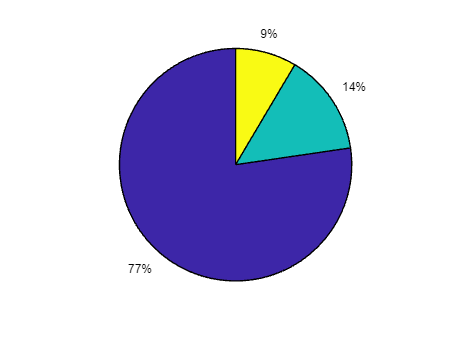

out =    77.3086   14.1706    8.5208


p =    77.3086   14.1706    8.5208


p = draw_pie(car_price)

% insurance price 
insurance_price = data(:, 15); 
insurance_price = normalize(insurance_price,"range");


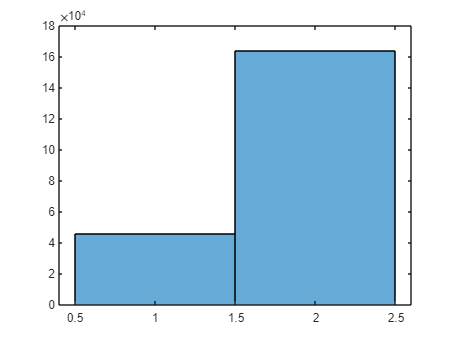

% other coverages 
other_coverage = data(:, 16);
other_coverage(find(other_coverage > 0)) = 2;
other_coverage(find(other_coverage == 0)) = 1;

histogram(other_coverage)

k =        45555      163533


p =    21.7875   78.2125


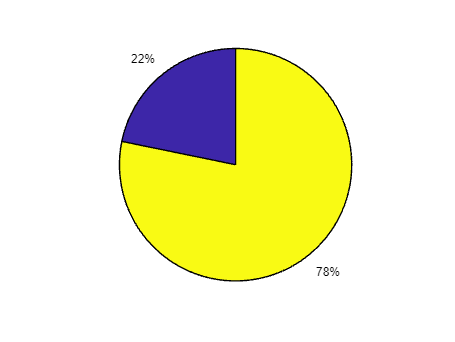

out =    21.7875   78.2125


p =    21.7875   78.2125


p = draw_pie(other_coverage)

% customer type 
customer_type = data(:, 18)

customer_type =      1
     1
     1
     1
     1
     1
     2
     1
     1
     1


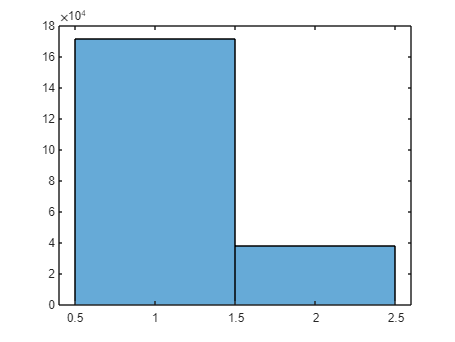

histogram(customer_type)

k =       171184       37904


p =    81.8717   18.1283


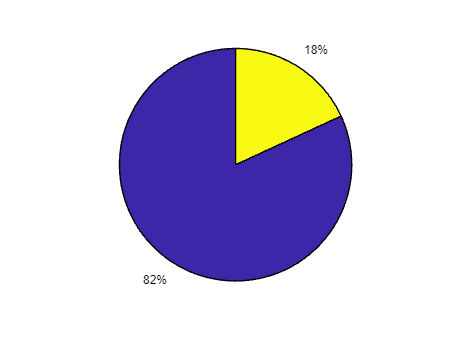

out = 1×2
   81.8717   18.1283


p = 1×2
   81.8717   18.1283



p = draw_pie(customer_type)

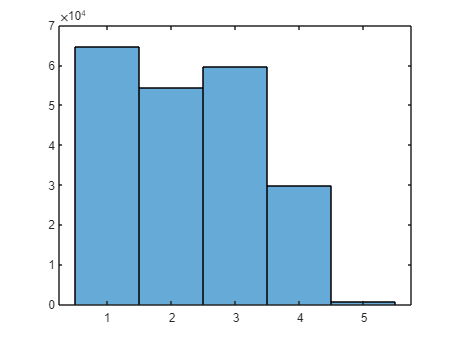

% car age 
car_age = data(:, 20);

car_age(find(car_age <= 2)) = 1;
car_age(find(car_age > 2 & car_age <= 5))   = 2;
car_age(find(car_age > 5 & car_age <= 10))  = 3;
car_age(find(car_age > 10 & car_age <= 20)) = 4;
car_age(find(car_age > 20))                 = 5;

histogram(car_age)

k = 1×5
       64613       54395       59603       29828         649


p = 1×5
   30.9023   26.0154   28.5062   14.2658    0.3104


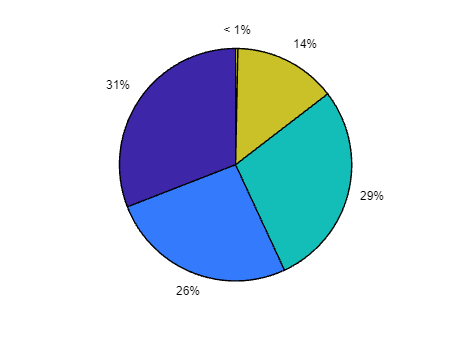

out = 1×5
   30.9023   26.0154   28.5062   14.2658    0.3104


ans = 1×5
   30.9023   26.0154   28.5062   14.2658    0.3104



draw_pie(car_age)

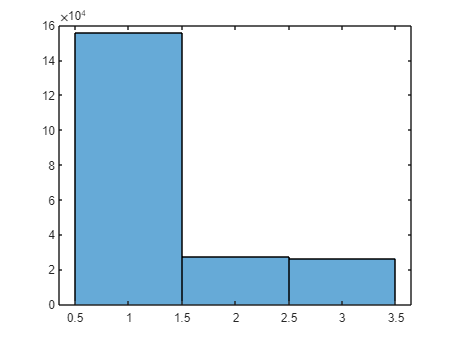

% car color 
car_color = data(:, 21);
histogram(car_color)

k = 1×3
      155650       27081       26357


p = 1×3
   74.4423   12.9520   12.6057


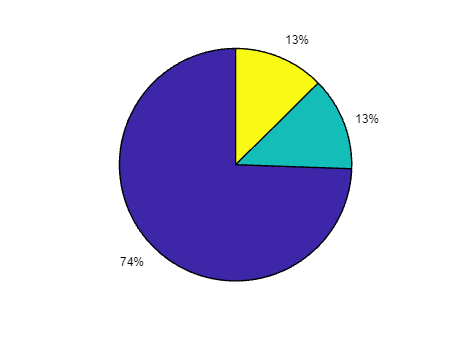

out = 1×3
   74.4423   12.9520   12.6057


p = 1×3
   74.4423   12.9520   12.6057


p = draw_pie(car_color)

% discounts 
discounts = data(:, 22);
discounts(find(discounts ~= 0 & discounts ~= 10 & discounts ~= 8)) = 2 

discounts = 209088×1
     2
     2
     0
     0
     2
     2
     2
     0
     2
     2


discounts(find(discounts == 0 | discounts == 10 | discounts == 8)) = 1

discounts = 209088×1
     2
     2
     1
     1
     2
     2
     2
     1
     2
     2


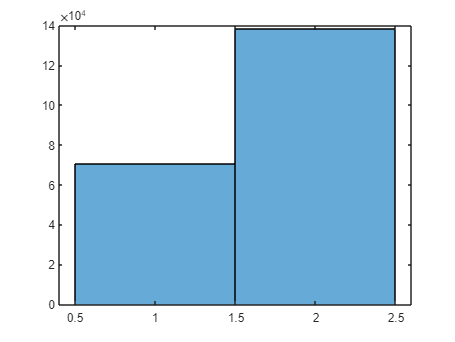

histogram(discounts)


histogram(discounts)

k = 1×2
       70791      138297


p = 1×2
   33.8570   66.1430


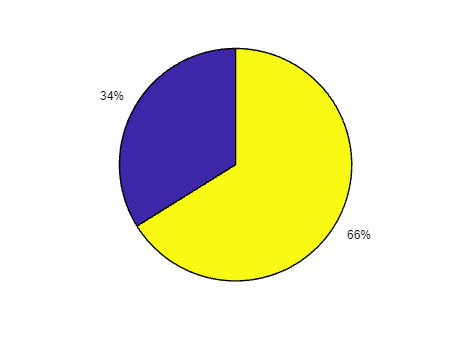

out = 1×2
   33.8570   66.1430


p = 1×2
   33.8570   66.1430


p = draw_pie(discounts)

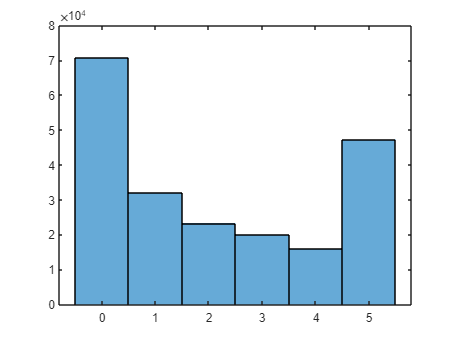

% Non Cliam Data
NCD = data(:, 22);
NCD(find(NCD > 6)) = 0;
histogram(NCD)


histogram(NCD)

k = 1×6
       70791       31991       23281       19917       15833       47275


p = 1×6
   33.8570   15.3003   11.1345    9.5257    7.5724   22.6101


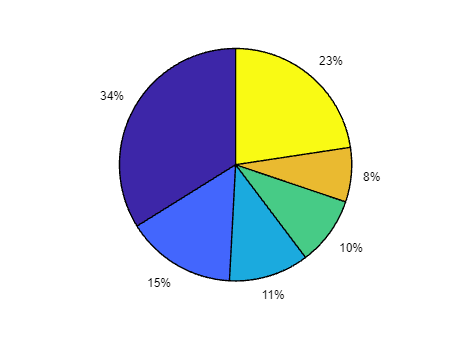

out = 1×6
   33.8570   15.3003   11.1345    9.5257    7.5724   22.6101


p = 1×6
   33.8570   15.3003   11.1345    9.5257    7.5724   22.6101


p = draw_pie(NCD)

% Settlement_delay_days
settlement_days = data(:, 23)

settlement_days = 209088×1
     0
     0
     8
     0
     0
     0
     0
     0
     0
     0


settlement_days = settlement_days (find(settlement_days ~= 0));
mean(settlement_days)

ans = 30.4528

std(settlement_days)

ans = 53.2193

max(settlement_days)

ans = 1398

min(settlement_days)

ans = 1

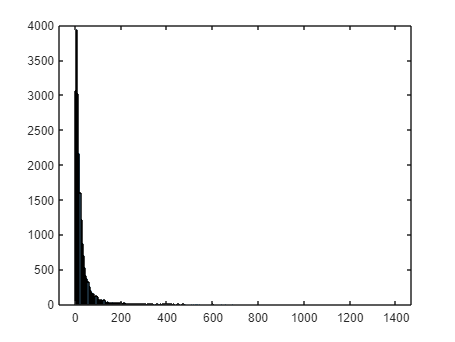

histogram(settlement_days)

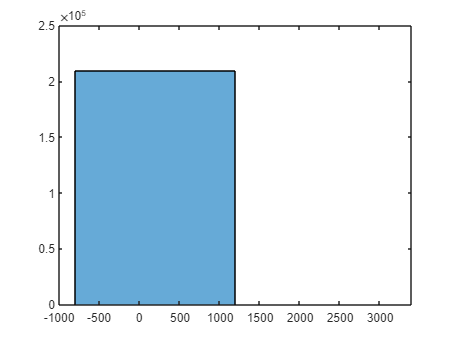

% reporting delay days
reporting_delay = data(:, 27);
% reporting_delay = reporting_delay(find(reporting_delay ~= 0));
histogram(reporting_delay,2)

% make the final dataset 
saman_dataset = [province_data, density_data, issue_date, car_type, car_usage, ...
                duration_policy, passengers, cylinders, car_price, insurance_price, ...
                other_coverage, customer_type, car_age, car_color, discounts, ...
                NCD];
csvwrite("normalized_saman_features.csv", saman_dataset);

## Generate and write labels to the file

% has the customer claim? 
has_claim = data(:, 24); 
has_claim(find(has_claim > 0)) = 1; 

% how much we should pay to the policyholder 
claim_amount = data(:, 25)

claim_amount = 209088×1
1.0e+10 *

         0
         0
    0.0038
         0
         0
         0
         0
         0
         0
         0


% payment month after its occurance 
payment_month = data(:, 23);

% write the targets to the file 
saman_labels = [has_claim, payment_month, claim_amount]

saman_labels = 209088×3
1.0e+10 *

         0         0         0
         0         0         0
    0.0000    0.0000    0.0038
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0
         0         0         0


csvwrite("saman_features_LABELs.csv", saman_labels);